# HDL Implementation of Three-Channel PWM

## Overview

The project was made for demonstration of capabilities of the Model-Based Design (MBD) approach in simple FPGA projects development process.

The process consists of three main parts: system design, testing, and HDL code generation with deployment.

For implementation of the task, algorithm of three-channel PWM generation was chosen. The system also has algorithms for duty cycles setting and channel number selection with the buttons and additional modules for pressing-of-the-button events processing.

All algorithms have requirement sets and simulation-based tests were developed and executed in order to prove that all modules work fine.

### Acknowledgments

The models are based on algorithms which were provided by Krivilyov A.V., D.Sc. (Technology), Full Professor at MAI.

## Modules

One can divide the system in three major parts:

- Processing of pressing-of-the-button events,

- Duty cycles generation,

- PWM generation.

The first part includes the following algorithms:

- Button Digital Filter (for all buttons),

- Rollover Handler,

- Pressing Mode Handler.

The second and the third parts are represented by Data Generator module and PWM Generator module, respectively.

Also, the system has Frequency Divider module.

open_system('main_model')

### IO

In system, five buttons are used:

- Up (increase the duty cycle),

- Down (decrease the duty cycle),

- Reset (set to zero duty cycles of all channels),

- Next (select the next channel),

- Previous (select the previous channel).

To observe PWM and synchronization signals, four digital outputs are used.

### Frequency Divider

Two frequency dividers modules (models) are used in project. They provide operation of the button filters and the PWM generator.

The module is based on the HDL Counter block from HDL Coder library and implements the up counter with maximum value N−1 where N is a module of the counter.

Word length of data equals $\lceil \log_{2}(N) \rceil$.

open_system('frequency_divider');

### Button Digital Filter

Digital filter is used in order to filter out the glitches associated with switch transitions (debouncing).

It is implemented as a shift register with three flip-flops including one T flip-flop for considering type of action (pressing or release). If all slots of the shift register equal to 0 then release event is formed; if all slots of the shift register equal to 1 then pressing event is formed.

A prescaler provides right operation frequency of the filter. The prescaler is based on filter period FLTR_PERIOD and target oscillator frequency CLK_FREQ. The prescalers value are calculated in the `calculatePrescalers` script.

edit calculatePrescalers.m

Variable FLTR_PERIOD is stored in the `filterDictionary.sldd` data dictioanary. Its default value is 1 ms.

open_system('button_filter');

### Rollover Handler

The model includes a rollover handler module which allows to correctly process several simultaneous buttonstrokes.

Only one button can be pressed at the same time. If any two o more buttons are pressed together then pressing event is not formed.

Permission generator function is a core of the algorithm. It generates variable `permit` as follows:

Then logical conjunction applies to this variable and corresponding button. For instance, `o_button_up = permit & i_button_up`.

open_system('rollover_handler');

### Pressing Mode Handler

Pressing mode handler processes user's pressing style. It supports single-pressing and continuous-pressing modes.

Core of the algorithm is a state machine which generates pulses when Up or Down button is pressed. It has three states: IDLE, PAUSE, and REPEATS. When signle-pressing event occurs, a pulse is generated. When user does not stop pressing one of the abovementioned button (continuous-pressing), then algorithm takes a pause duration of which is determined by the parameter PAUSE_PRD. If during the pause user does not stop pressing, algorithm starts to generate pulses with at regular intervals, duration of the interval is determined by the parameter REPEATS_PRD. After user stops pressing, state machine goes to IDLE state.

Then logical conjunction applies to the pulse and corresponding button. For instance, `o_button_up = pulse & i_button_up`.

All parameters of the handler are stored in `pulsesgenDictionary.sldd` data dictionary.

open_system('control_pulses_generator');

### Data Generator

Data generator module forms duty cycles for all three channel. It consists of two state machines.

The first selects PWM channel using NEXT and PREVIOUS button. It has closed-loop structure with three states: FIRST (default state), SECOND, and THIRD. Every state is responsible for corresponding channel. If state machine is in FIRST state then the first channel is currently active, and so on. The states switch in the following sequence: FIRST -> SECOND -> THIRD -> FIRST (forward direction) and FIRST -> THIRD -> SECOND -> FIRST (inverse direction).

The second state machine forms duty cycles according to PWM channel using UP, DOWN, and RESET buttons. It has three states: IDLE (default state), UP, and DOWN. When state machine is in IDLE state then all duty cycles (duty cycles for all channels) are equal to zero. When UP button is pressed, summative counter of corresponding channel starts to work until counter limit is reached. Otherwise, when DOWN button is pressed, subtractive counter corresponding channel starts to work until zero is reached. When RESET button is pressed then state machine goes to IDLE state.

The module has one parameter - counter size - with which one can set PWM size. Default value is 5 bits. It is stored in `datacounterDictionary.sldd` data dictionary.

open_system('data_counter');

### PWM Generator

PWM generator module generates PWM signals using duty cycles. It is based on counter-comparing operation. In the module, there are three types of counters in accordance with PWM type: summative (FRONT type), subtractive (BACK type), and reversed (CENTERED type). Each of them has three outputs: current counter value, synch condition, and end-of-period flag. Synch condition generates signal relative to which PWM signal aligns, end-of-period flag tells algorithm when it is necessary to load new duty cycle data from the data generator module.

PWM type and PWM frequency parameters are stored in `pwmgenDictionary.sldd` data dictionary. It is worth to note that all three PWM signals has the same frequency.

open_system('pwm_generator');

For test sequencies creation, I have written a script `createTestSignalsForPWM` 

edit createTestSignalsForPWM.m

## Data Dictionaries

The project contains six data dictionaries for each component:

- `filterDictionary.sldd` stores parameters of button filters;

- `pulsesgenDictionary.sldd` stores parameters of pressing mode handler;

- `datacounterDictionary.sldd` stores parameters of data generator;

- `pwmgenDictionary.sldd` stores parameters of PWM generator;

- `targetDictionary.sldd` stores parameters of FPGA;

- `mainDictionary.sldd` is a high-level dictionary.

The following parameters of the system are used (by default):

Parameter            Value                    Unit

SIZE                    5                            -

FLTR_PRD          0.001                    sec

PAUSE_PRD      1                           sec

REPEATS_PRD  0.1                       sec

TYPE                   Types of PWM    -

PWM_FREQ        5e4                     Hz

CLK_FREQ         2e8                     Hz

Variable TYPE is an enumeration type and has three values: FRONT, BACK, and CENTERED.

## Simulation & Experiments

In this section, you can see the results of experiments and comparison of experiments with simulation.

Before the deployment, it is useful to check whether models are suitable for HDL code generation or not. For this reason, I have written a script `checkHDLCompatibility`

edit checkHDLCompatibility.m

The script uses calls a function `checksubsystemcompatibility()` which uses built-in function `checkhdl()` (HDL Coder).

edit checksubsystemcompatibility.m

[Virtex-6 FPGA ML605 Evaluation Kit](https://www.xilinx.com/products/boards-and-kits/ek-v6-ml605-g.html) was chosen as a target for experiments.

Nine experiments were carried out:

- three with trailing edge modulation PWM;

- three with leading edge modulation PWM;

- three with centered pulses PWM.

Data from oscilloscope was transfered to MATLAB and processed there in order to realize appropriate comparison.

In the figures at right, simulation results are depicted:

- S - synch (yellow line);

- P1 - the first channel of PWM (green line);

- P2 - the second channel of PWM (blue line);

- P3 - the third channel of PWM (red line).

Black lines over them are experimental data of corresponding signal.

### Trailing edge modulation (back)

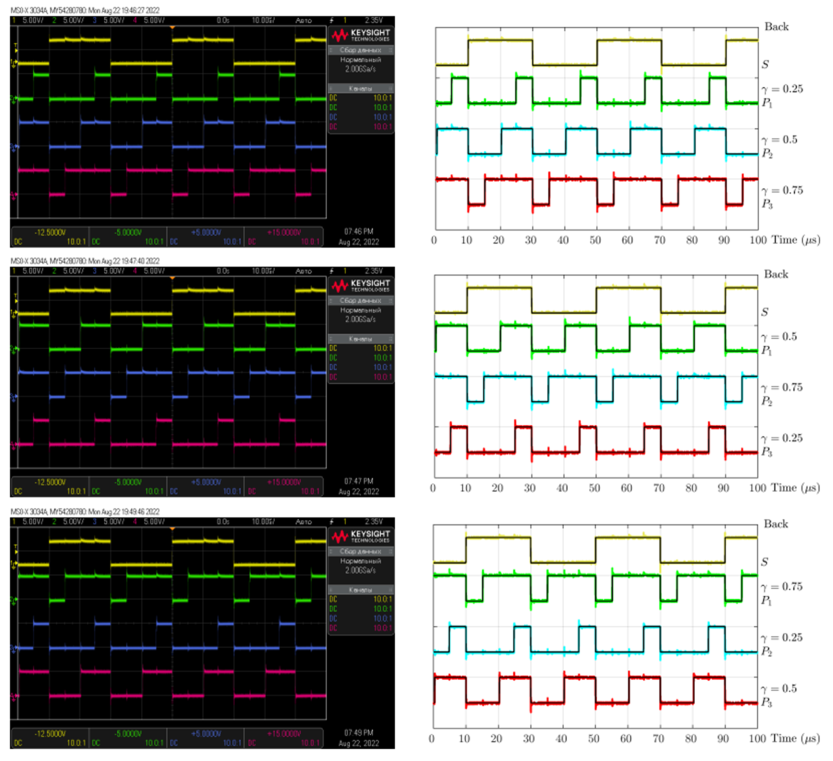

### Leading edge modulation (front)

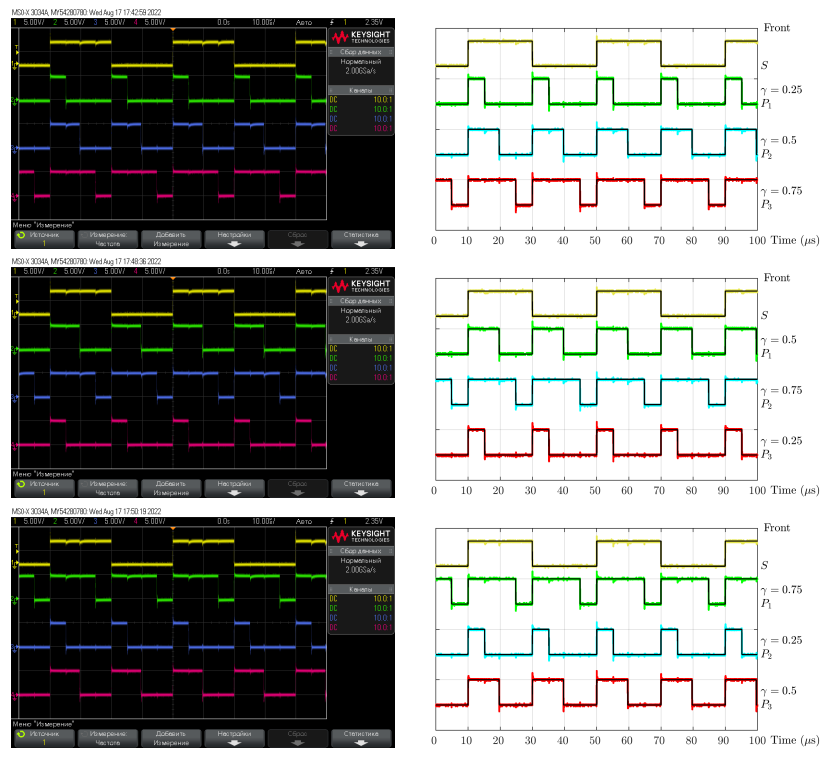

### Centered pulses (centered)